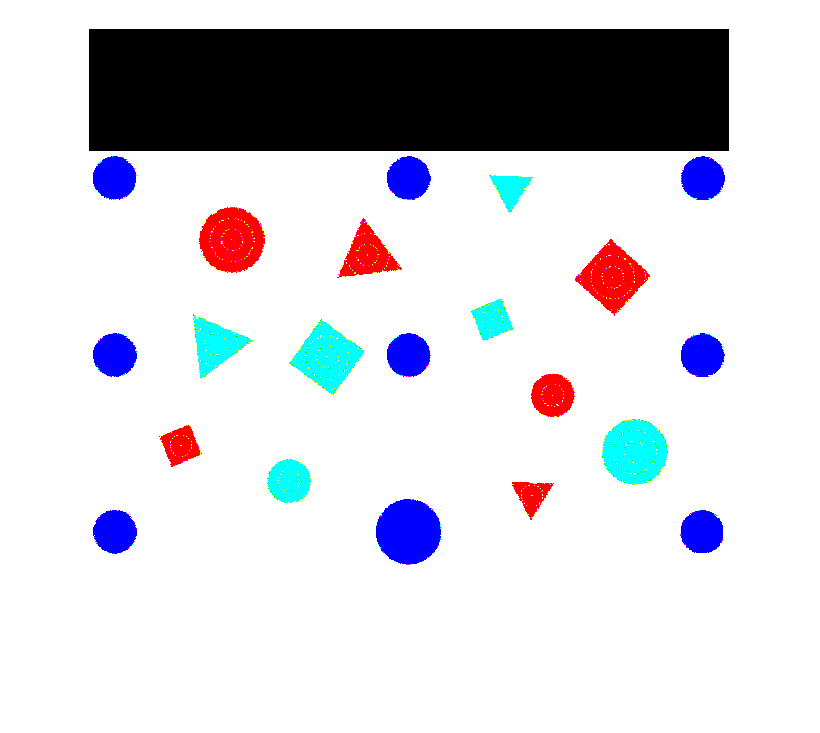

% sim = coppeliaRobot();


q = [0 -24 -21 45 0]; % Perfect for top view picture
q0 = [0 0 0 0 0];
setJointPositions(sim, q);

% % Capture image
pause(3);
% Turn to DOUBLE
image = double(getImage(sim));
image(1:122,:,:) = 0;
imshow(image)

## Get info Init, Dest, Coords


% ---

rowNum = 6

data = 12×6 string array
    "red"      "Square"      "92.0975"     "417.103"     "1097"    "False"
    "red"      "Circle"      "143.6097"    "211.5715"    "3400"    "True" 
    "red"      "Triangle"    "279.1226"    "226.252"     "1893"    "True" 
    "red"      "Triangle"    "443.3682"    "466.8706"    "850"     "False"
    "red"      "Circle"      "464.3187"    "366.9236"    "1506"    "False"
    "red"      "Square"      "524.1512"    "248.785"     "3009"    "True" 
    "green"    "Triangle"    "126.9635"    "316.1148"    "1890"    "True" 
    "green"    "Circle"      "200.5683"    "452.7182"    "1515"    "False"
    "green"    "Square"      "238.5533"    "328.7404"    "3009"    "True" 
    "green"    "Square"      "403.6868"    "291.3973"    "1095"    "False"
    "green"    "Triangle"    "422.1894"    "160.3765"    "850"     "False"
    "green"    "Circle"      "546.2184"    "423.3523"    "3383"    "True" 


init_image = double(imread("init_image2.jpg"));
dest_image = double(imread("init_image3.jpg"));
% ---

data = extractData(image, 1600)
initData = extractData(init_image, 37260)

rowNum = 1

initData = 3×6 string array
    "red"      "Triangle"    "221.9585"    "265.9048"    "38079"    "True" 
    "red"      "Circle"      "808.3106"    "266.0922"    "68322"    "True" 
    "green"    "Triangle"    "515.1408"    "266.0029"    "17175"    "False"


destData = extractData(dest_image, 37260)

rowNum = 2

destData = 3×6 string array
    "red"      "Square"      "219.0041"    "260.9999"    "59049"    "True" 
    "green"    "Square"      "509.5238"    "260.4973"    "21591"    "False"
    "green"    "Triangle"    "798.8596"    "253.5989"    "37406"    "True" 


init_xy_image = zeros(2,3);

init_xy_image =      0     0     0
     0     0     0


for i=1:3
    temp1 = [data(:,1)==initData(i,1) data(:,2)==initData(i,2) data(:,6)==initData(i,6)];
    temp2 = temp1(:,1) + temp1(:,2) + temp1(:,3)
    postition = find(temp2==3)
    init_xy_image(1,i) = str2num(data(postition, 3));
    init_xy_image(2,i) = str2num(data(postition, 4));
end

temp2 =      1
     2
     3
     2
     1
     2
     2
     0
     1
     0


postition = 3

temp2 =      1
     3
     2
     1
     2
     2
     1
     1
     1
     0


postition = 2

temp2 =      1
     0
     1
     2
     1
     0
     2
     2
     1
     2


postition = 11

init_xy_image

init_xy_image =   279.1226  143.6097  422.1894
  226.2520  211.5715  160.3765



dest_xy_image = zeros(2,3);

dest_xy_image =      0     0     0
     0     0     0


for i=1:3
    temp1 = [data(:,1)==destData(i,1) data(:,2)==destData(i,2) data(:,6)==destData(i,6)];
    temp2 = temp1(:,1) + temp1(:,2) + temp1(:,3)
    postition = find(temp2==3)
    dest_xy_image(1,i) = str2num(data(postition, 3));
    dest_xy_image(2,i) = str2num(data(postition, 4));
end

temp2 =      2
     2
     2
     1
     1
     3
     1
     0
     2
     1


postition = 6

temp2 =      2
     0
     0
     1
     1
     1
     1
     2
     2
     3


postition = 10

temp2 =      0
     1
     2
     1
     0
     1
     3
     1
     2
     1


postition = 7

dest_xy_image

dest_xy_image =   524.1512  403.6868  126.9635
  248.7850  291.3973  316.1148


## Homography

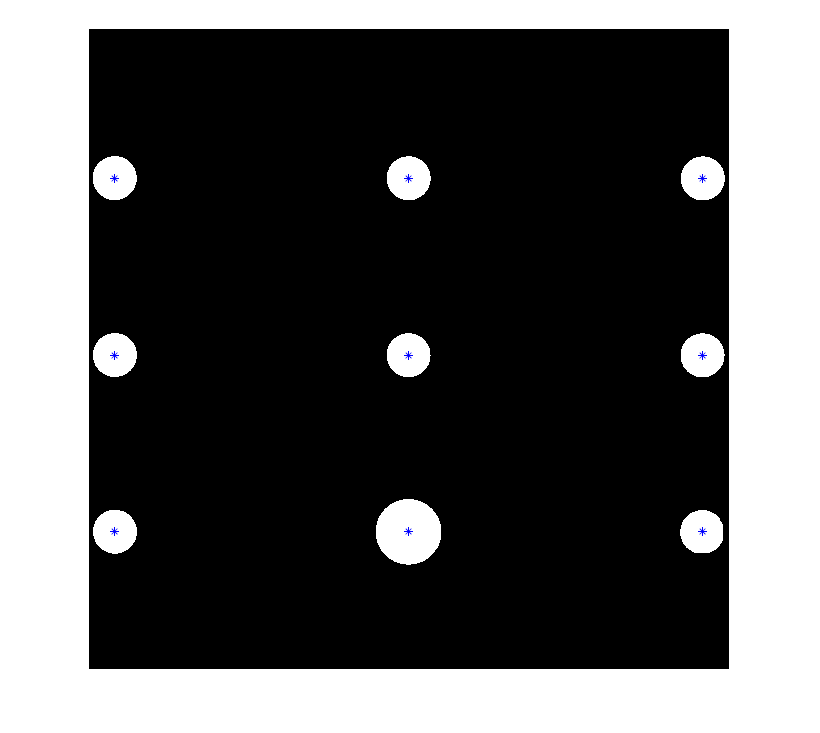

% Get colour plains
red = image(:,:,1);
green = image(:,:,2);
blue = image(:,:,3);

% Clean noise, Get blue circles
blueCircles = imclose(blue./(red+green+blue) > 0.6, ones(5,5));

% Get blue shapes' stats
blueStats = regionprops("table",blueCircles,"Centroid","Area","Circularity");
imshow(blueCircles)
hold on
plot(blueStats.Centroid(:,1),blueStats.Centroid(:,2),"b*")
hold off


% Store data
blueCentroids = cat(1,blueStats.Centroid);
blueAreas = cat(1,blueStats.Area);

% Left bottom circle = start circle
startCircleCentroid = [min(blueCentroids(:,1))+10 max(blueCentroids(:,2))-10]

startCircleCentroid =    36.2294  493.4053



i = [blueCentroids(:,1) < startCircleCentroid(1),  blueCentroids(:,2) > startCircleCentroid(2)]

i = 9×2 logical array
   1   0
   1   0
   1   1
   0   1
   0   0
   0   0
   0   1
   0   0
   0   0


i = i(:,1)+i(:,2)

i =      1
     1
     2
     1
     0
     0
     1
     0
     0


startPosition = find(i==2)

startPosition = 3


% Clone variable
centroidsNew = blueCentroids;
% Remove the largest circle
centroidsNew(startPosition,:) = [];
% 3rd column: Calculate and add distanceFromLargest circle
distanceFromLargest = [centroidsNew, sqrt(abs(centroidsNew(:,1)-blueCentroids(startPosition,1)).^2 + abs(centroidsNew(:,2)-blueCentroids(startPosition,2)).^2)];
% 4th column: Add sum of coordinates
distanceFromLargest = [distanceFromLargest, distanceFromLargest(:,1)+distanceFromLargest(:,2)];
% Sort in the ascending order of distanceFromLargest
distanceSorted = sortrows( distanceFromLargest, 3);
sorted3 = sortrows( distanceSorted(1:3,:), 4);
sorted5 = sortrows( distanceSorted(4:8,:), 4);
% Now put them in P, order is right as required
P = [blueCentroids(startPosition,1:2)' sorted3(:,1:2)' sorted5(:,1:2)' ; ones(1,9) ]

P =    26.4733   26.4049  320.0640  320.0331   26.2294  320.1853  614.3607  614.0244  613.5500
  503.1806  326.5313  326.6686  503.3398  149.5898  149.7234  149.8968  326.7770  503.4053
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


% The Euclidean workspace coordinates of the markers
Q = [ 20 182.5 182.5 20 345 345 345 182.5 20;  560 560 290 290 560 290 20 20 20;  ones(1,9) ]

Q =    20.0000  182.5000  182.5000   20.0000  345.0000  345.0000  345.0000  182.5000   20.0000
  560.0000  560.0000  290.0000  290.0000  560.0000  290.0000   20.0000   20.0000   20.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


H = simple_homography(P,Q)

H =     0.0004   -0.9186  482.1722
   -0.9175   -0.0020  583.9492
    0.0000   -0.0000    1.0000




% Get realworld initial coordinates
init_xy = zeros(2,3);
init_xy_image = [init_xy_image;  ones(1,3)];

temp_xy = H * init_xy_image(:,1);
init_xy(:,1) = temp_xy(1:2,:)./temp_xy(3,:);

temp_xy = H * init_xy_image(:,2);
init_xy(:,2) = temp_xy(1:2,:)./temp_xy(3,:);

temp_xy = H * init_xy_image(:,3);
init_xy(:,3) = temp_xy(1:2,:)./temp_xy(3,:);
init_xy

init_xy =   274.7410  288.1670  335.2722
  327.7426  452.2144  196.4024



% Get realworld destination coordinates
dest_xy = zeros(2,3);
dest_xy_image = [dest_xy_image;  ones(1,3)];

temp_xy = H * dest_xy_image(:,1);
dest_xy(:,1) = temp_xy(1:2,:)./temp_xy(3,:);

temp_xy = H * dest_xy_image(:,2);
dest_xy(:,2) = temp_xy(1:2,:)./temp_xy(3,:);

temp_xy = H * dest_xy_image(:,3);
dest_xy(:,3) = temp_xy(1:2,:)./temp_xy(3,:);
dest_xy

dest_xy =   254.1452  214.9495  192.1225
  102.6433  213.2619  467.5283
